Training on single GPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:03 |         6.06 |         18.3 |          0.0010 |
|      50 |          50 |       00:00:08 |         2.75 |          3.8 |          0.0010 |
|     100 |         100 |       00:00:12 |         1.18 |          0.7 |          0.0010 |
|     150 |         150 |       00:00:16 |         0.54 |          0.1 |          0.0010 |
|     200 |         200 |       00:00:20 |         0.25 |      3.2e-02 |          0.0010 |
|     250 |         250 |       00:00:24 |         0.19 |      1.8e-02 |          0.0010 |
|     300 |         300 |       00:00:28 |         0.17 |      1.4

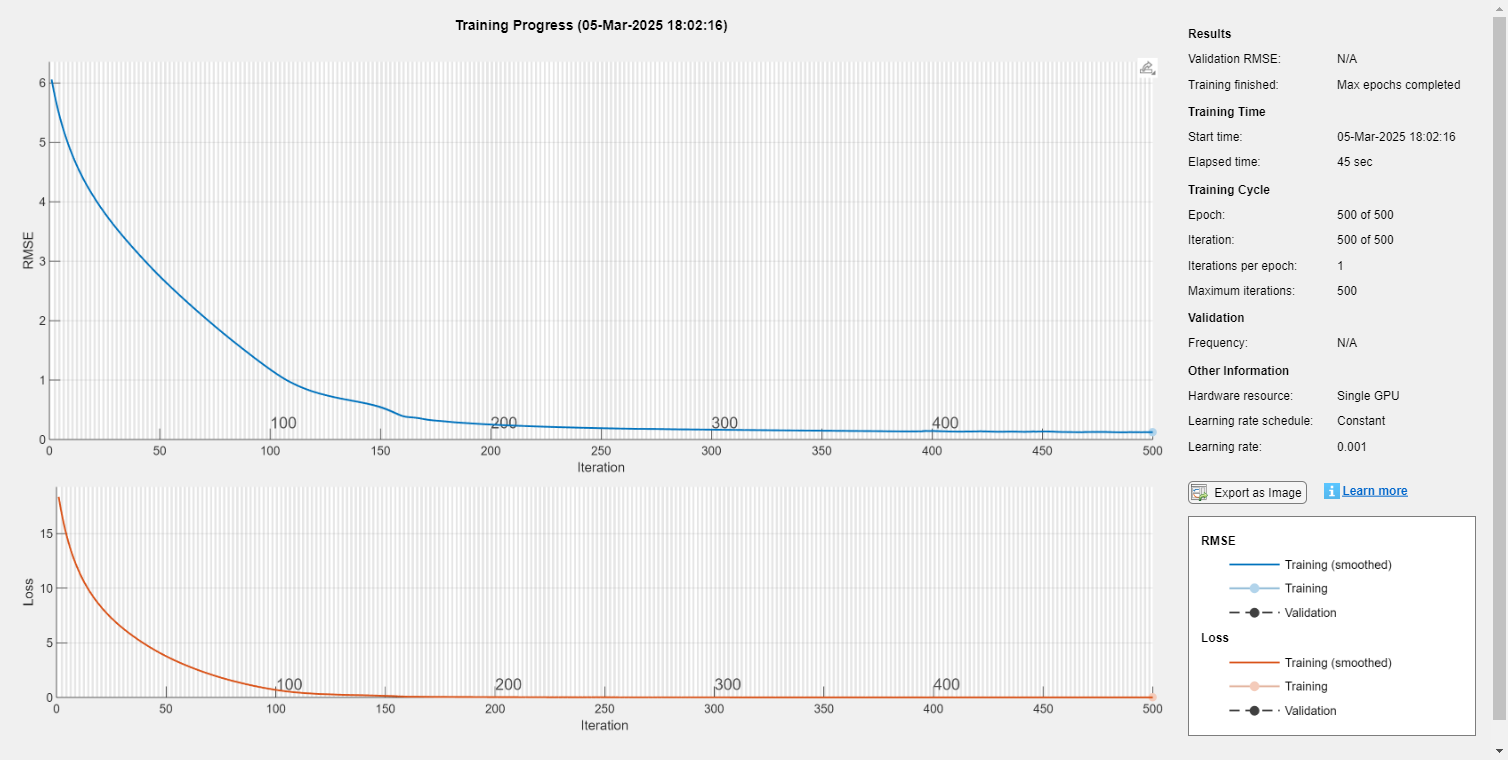

%%%% Load Pretrained Autoencoder Weights & Biases %%%%
we = autoenc5.EncoderWeights;  
be = autoenc5.EncoderBiases;  
wd = autoenc5.DecoderWeights;
bd = autoenc5.DecoderBiases;
%%%% Define BILSTM Network with Pretrained Weights %%%%
outPut_Size = size(we, 1);  % Should match encoded feature size (latent space)
inputSize = size(we, 2);    % Original waveform feature size

outPut_Sizedec = size(wd, 1);  % Should match encoded feature size (latent space)
inputSizedec = size(wd, 2);    % Original waveform feature size

layerenc = fullyConnectedLayer(outPut_Size, ...
    'Weights', we, ...
    'Bias', be);

layerdec = fullyConnectedLayer(outPut_Sizedec, ...
    'Weights', wd, ...
    'Bias', bd);

% Ensure LSTM output matches the decoder input size
lstm_output_size = inputSizedec; % Should match `size(wd, 2)`

% Define LSTM-based Architecture
layers = [
    sequenceInputLayer(inputSize)
    layerenc
    lstmLayer(lstm_output_size, 'OutputMode', 'sequence') % Use correct LSTM size
    layerdec
    fullyConnectedLayer(outPut_Sizedec) % Match decoder output size
    regressionLayer];


%%%% Training Options %%%%
options = trainingOptions('adam', ...
   'Plots', 'training-progress', ...
   'MiniBatchSize', 500, ...
   'MaxEpochs', 500, ...
   'SequencePaddingDirection','left',...
   'Shuffle', 'every-epoch', ...
   'GradientThreshold', 1, ...
   'Verbose', true, ...
   'ExecutionEnvironment', 'auto');

%%%% Reshape Data for LSTM %%%%
testwaveformDataSeq = permute(testwaveformData, [2, 1]); % Ensure correct format for LSTM

%%%% Train the Model %%%%
net = trainNetwork(testwaveformDataSeq', testwaveformDataSeq', layers, options);